load squeezenet.mat
signds = imageDatastore("D:\college\FYP\Experimenting\test\stopping","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;
[signTrain,signTest] = splitEachLabel(signds,0.8,"randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([227 227],signTrain);
resizeTestImgs = augmentedImageDatastore([227 227],signTest);

numClasses = numel(categories(signds.Labels));

% Setting Options
opts = trainingOptions("sgdm","InitialLearnRate",0.001,"MaxEpochs",5,"VerboseFrequency",2);

% Training the network
[Network,info] = trainNetwork(resizeTrainImgs,squeezenet,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       46.51% |       2.3292 |          0.0010 |
|       2 |           2 |       00:00:14 |       50.00% |       4.6570 |          0.0010 |
|       4 |           4 |       00:00:28 |       76.74% |       0.5195 |          0.0010 |
|       5 |           5 |       00:00:35 |       58.14% |       0.6435 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


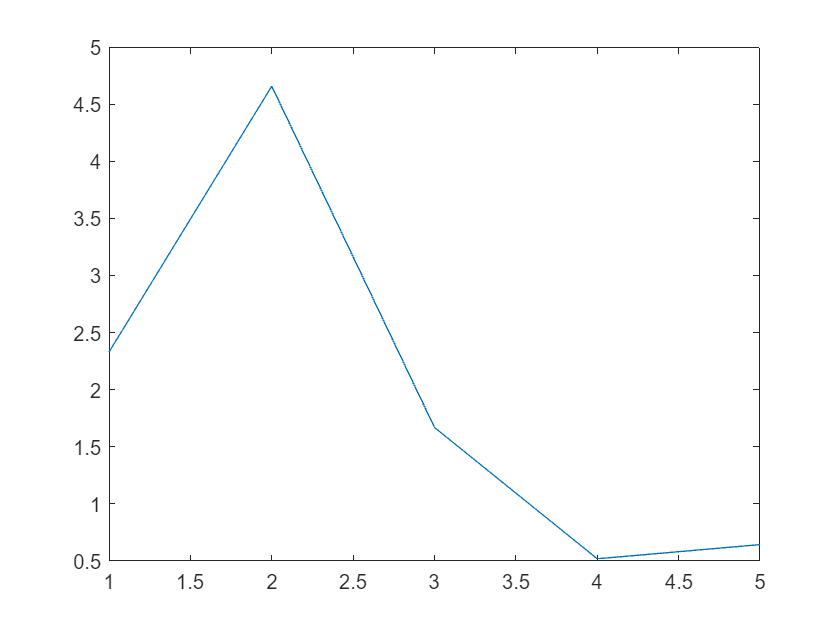


% Evaluating Performance
plot(info.TrainingLoss);

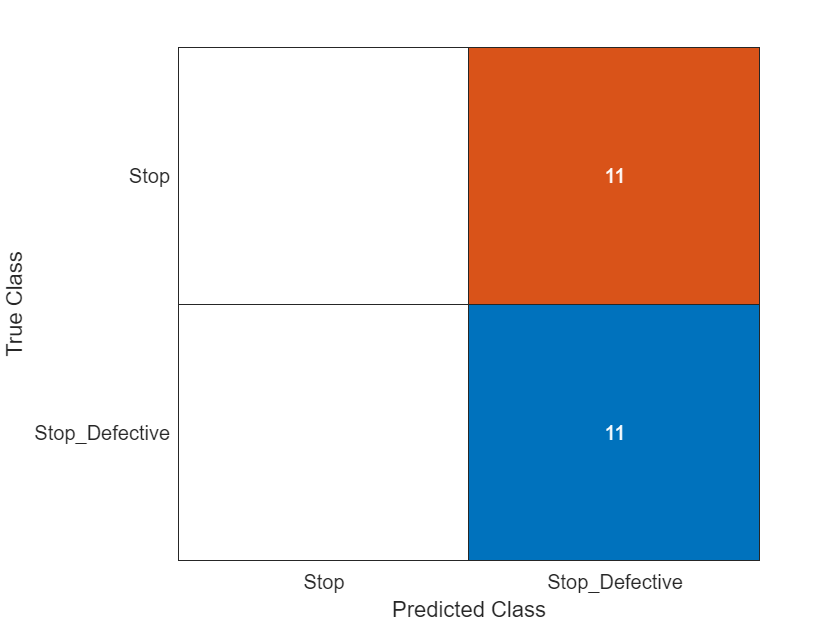



% Prediction
signPrediction = classify(Network,resizeTestImgs);

signActual = signTest.Labels;

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect/numel(signPrediction);

% Confusion Chart
confusionchart(signActual,signPrediction);